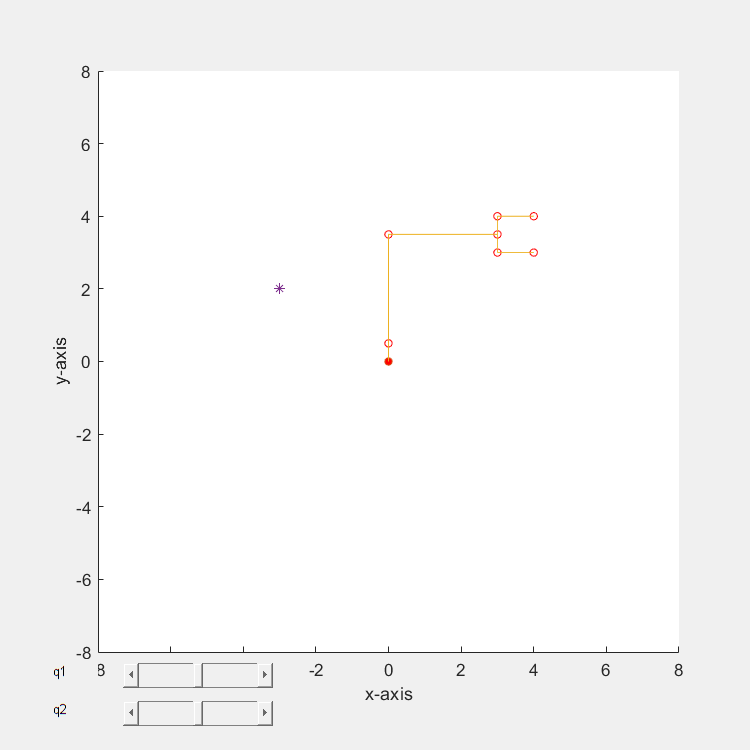

Robot_Simulator

function Robot_Simulator()
    % Create a figure for the plot
    fig = figure('Position', [100, 100, 600, 600]);
    
    % Create axes
    ax = axes('Parent', fig);
    hold(ax, 'on');
    
    % Create sliders for interactive input
    sld1 = uicontrol('Style', 'slider', 'Min', -180, 'Max', 180, 'Value', 0, ...
        'Position', [100, 50, 120, 20], 'Callback', @(src, event) updatePlot());
    sld2 = uicontrol('Style', 'slider', 'Min', -180, 'Max', 180, 'Value', 0, ...
        'Position', [100, 20, 120, 20], 'Callback', @(src, event) updatePlot());
    
    % Create text labels for the sliders
    lbl1 = uicontrol('Style', 'text', 'Position', [20, 50, 60, 20], 'String', 'q1');
    lbl2 = uicontrol('Style', 'text', 'Position', [20, 20, 60, 20], 'String', 'q2');
    
    % Update the plot based on slider values
    function updatePlot()
        q1 = get(sld1, 'Value');
        q2 = get(sld2, 'Value');

        % Convert from degrees to radians
        a1 = q1 / 180 * pi;
        a2 = q2 / 180 * pi;

        % Define robot geometry
        d1 = 0.5;
        d2 = 3;
        de = 3;

        % Define target
        target = [-3; 2; 1];
        
        % Define the end effector points
        pe = [1, 0.5, 1; 0, 0.5, 1; 0, -0.5, 1; 1, -0.5, 1; 0, -0.5, 1; 0, 0, 1]';

        % Define transformation matrices
        Je = [1, 0, de; 0, 1, 0; 0, 0, 1];
        J2 = [cos(a2), -sin(a2), 0; sin(a2), cos(a2), d2; 0, 0, 1];
        J1 = [cos(a1), -sin(a1), 0; sin(a1), cos(a1), d1; 0, 0, 1];

        % Propagate transformations
        p = [Je * pe, [0; 0; 1]];
        p = [J2 * p, [0; 0; 1]];
        p = [J1 * p, [0; 0; 1]];

        % Clear the previous plot
        cla(ax);

        % Plot the points
        scatter(ax, p(1, :), p(2, :), 20, 'MarkerEdgeColor', 'r');
        scatter(ax, 0, 0, 20, 'MarkerFaceColor', 'r');
        plot(ax, p(1, :), p(2, :), '-');
        plot(ax, target(1), target(2), '*');
        axis(ax, 'equal');
        xlim(ax, [-8, 8]);
        ylim(ax, [-8, 8]);
        xlabel(ax, 'x-axis');
        ylabel(ax, 'y-axis');
    end

    % Initialize the plot
    updatePlot();
end
